# Filtro de Wiener

Se defiene parametros para la señal y el filtro

N = 500; % Longitud de la señal
%SNR = 5; % Relación señal/ruido en dB
L = 5; % Longitud del filtro

Generacion de la señal original (sin ruido)

n = 0:N-1;
xn = 20 + 0.05 * n; % Tendencia lineal
%xn = 3*cos(2*pi*0.01*n) - 2*sin(2*pi*0.05*n);
%ruido
%r = randn(N, 1) * std(xn) / 10^(SNR/20);
r = randn(N, 1);
% señal + ruido
xn_r = xn +r';


Estimación de la correlacion cruzada entre la señal ruidosa y la original

Rxy = xcorr(xn_r, xn, L, 'unbiased'); % Correlacion cruzada entre y y x
Rxy = Rxy(L+1:end);

Estimación de la matriz de correlacion de la señal ruidosa

Ryy = xcorr(xn_r, L, 'unbiased');
Ryy = Ryy(L+1:end);
Ryy_matrix = toeplitz(Ryy);

Cálculo de los coeficientes del filtro de Wiener y filtrado de la señal

%w = Rxy ./ Ryy;
w = Rxy / Ryy_matrix;
yn = filter(w,1,xn_r);

Graficas de las señales

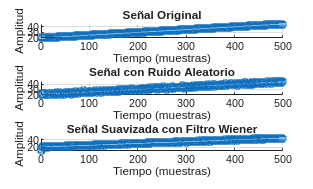

figure()

% Graficar la señal original (tendencia)
subplot(3,1,1);
scatter(n, xn);
title('Señal Original');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

% Graficar la señal ruidosa
subplot(3,1,2);
scatter(n, xn_r);
title('Señal con Ruido Aleatorio');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

% Graficar la señal suavizada (filtro AR)
subplot(3,1,3);
scatter(n, yn);
title('Señal Suavizada con Filtro Wiener');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

## Mediciones sobre las señales

Se aplicaran mediciones para verificar el efecto del filtro Wiener sin contemplar el transitorio

Primero entre la señal original y la señal ruidosa

% Error cuadratico medio (MSE)
Err1 = (1/(N-L)) *(sum( (xn(L:end) - xn_r(L:end)) .^ 2))

Err1 = 0.9618

Ahora entre la señal original y la señal suavizada

Err2 = (1/(N-L)) *(sum( (xn(L:end) - yn(L:end)) .^ 2))

Err2 = 0.2848